clear all
close all

MUA = load("D:\V1_Cortex_Paper\MultichannelDataTanks\spiketable_Aud_Sig_MUA_revised.mat");
MUA = MUA.spiketable;
MUA_indx = load("D:\V1_Cortex_Paper\MultichannelDataTanks\NormalizedIndexesTable_MUA_revised.mat");
MUA_indx = MUA_indx.NormalizedIndexesTableMUA;
UN = load("D:\V1_Cortex_Paper\MultichannelDataTanks\spiketable_Aud_Sig_revised.mat");
UN = UN.spiketable;
UN_indx = load("D:\V1_Cortex_Paper\MultichannelDataTanks\NormalizedIndexesTable_revised.mat");
UN_indx = UN_indx.NormalizedIndexesTable;

% Define file path
filePath = 'D:\V1_Cortex_Paper\Tungsten_Recordings\Excel\UnitTable_V1_PCA_Julio2025.xlsx';

% Read the first sheet into a table
unitTable = readtable(filePath, 'Sheet', 1);

W_UN_indx = load("D:\V1_Cortex_Paper\Tungsten_Recordings\NormalizedIndexesTableC.mat");
W_UN_indx = W_UN_indx.NormalizedIndexesTableC;

n = 1;
m = 1;
p = 1;
t = 1;
s = 1;
r = 1;

for i = 1:size(MUA,1)
    if MUA.layer(i) == 4 && MUA.Auditory(i) && MUA.Significance(i) == 0
        Layer4_Aud(n,:) = MUA_indx(i,:); 
        n = n + 1;
    end
end

for i = 1:size(MUA,1)
    if MUA.layer(i) == 4 && MUA.Significance(i)
        Layer4_Sig(r,:) = MUA_indx(i,:); 
        r = r + 1;
    end
end

for i = 1:size(MUA,1)
    if MUA.layer(i) == 5 && MUA.Auditory(i) && MUA.Significance(i) == 0
        Layer5_Aud(m,:) = MUA_indx(i,:); 
        m = m + 1;
    end
end

for i = 1:size(MUA,1)
    if MUA.layer(i) == 5 && MUA.Significance(i)
        Layer5_Sig(s,:) = MUA_indx(i,:); 
        s = s + 1;
    end
end

for i = 1:size(MUA,1)
    if MUA.layer(i) == 6 && MUA.Auditory(i) && MUA.Significance(i) == 0
        Layer6_Aud(p,:) = MUA_indx(i,:); 
        p = p + 1;
    end
end

for i = 1:size(MUA,1)
    if MUA.layer(i) == 6 && MUA.Significance(i)
        Layer6_Sig(t,:) = MUA_indx(i,:); 
        t = t + 1;
    end    
end

for i = 1:size(UN,1)
    if UN.layer(i) == 4 && UN.Auditory(i) && UN.Significance(i) == 0
        Layer4_Aud(n,:) = UN_indx(i,:); 
        n = n + 1;
    end
end
for i = 1:size(UN,1)
    if UN.layer(i) == 4 && UN.Significance(i)
        Layer4_Sig(r,:) = UN_indx(i,:); 
        r = r + 1;
    end
end
for i = 1:size(UN,1)
    if UN.layer(i) == 5 && UN.Auditory(i) && UN.Significance(i) == 0
        Layer5_Aud(m,:) = UN_indx(i,:); 
        m = m + 1;
    end
end
for i = 1:size(UN,1)
    if UN.layer(i) == 5 && UN.Significance(i)
        Layer5_Sig(s,:) = UN_indx(i,:); 
        s = s + 1;
    end
end
for i = 1:size(UN,1)
    if UN.layer(i) == 6 && UN.Auditory(i) && UN.Significance(i) == 0
        Layer6_Aud(p,:) = UN_indx(i,:); 
        p = p + 1;
    end
end
for i = 1:size(UN,1)
    if UN.layer(i) == 6 && UN.Significance(i)
        Layer6_Sig(t,:) = UN_indx(i,:); 
        t = t + 1;
    end  
end

for i = 1:size(W_UN_indx,1)
    if unitTable.Layer(i) == 4 && unitTable.Auditory(i) && unitTable.Significance(i) == 0
        Layer4_Aud(n,:) = W_UN_indx(i,:); 
        n = n + 1;
    end
end
for i = 1:size(W_UN_indx,1)
    if unitTable.Layer(i) == 4 && unitTable.Significance(i)
        Layer4_Sig(r,:) = W_UN_indx(i,:); 
        r = r + 1;
    end
end
for i = 1:size(W_UN_indx,1)
    if unitTable.Layer(i) == 5 && unitTable.Auditory(i) && unitTable.Significance(i) == 0
        Layer5_Aud(m,:) = W_UN_indx(i,:); 
        m = m + 1;
    end
end
for i = 1:size(W_UN_indx,1)
    if unitTable.Layer(i) == 5 && unitTable.Significance(i)
        Layer5_Sig(s,:) = W_UN_indx(i,:); 
        s = s + 1;
    end
end
for i = 1:size(W_UN_indx,1)
    if unitTable.Layer(i) == 6 && unitTable.Auditory(i) && unitTable.Significance(i) == 0
        Layer6_Aud(p,:) = W_UN_indx(i,:); 
        p = p + 1;
    end
end
for i = 1:size(W_UN_indx,1)
    if unitTable.Layer(i) == 6 && unitTable.Significance(i)
        Layer6_Sig(t,:) = W_UN_indx(i,:); 
        t = t + 1;
    end  
end

folder = 'D:\V1_Cortex_Paper\MultichannelDataTanks\';
save(fullfile(folder, 'Layer4_Aud.mat'), 'Layer4_Aud');
save(fullfile(folder, 'Layer4_Sig.mat'), 'Layer4_Sig');
save(fullfile(folder, 'Layer5_Aud.mat'), 'Layer5_Aud');
save(fullfile(folder, 'Layer5_Sig.mat'), 'Layer5_Sig');
save(fullfile(folder, 'Layer6_Aud.mat'), 'Layer6_Aud');
save(fullfile(folder, 'Layer6_Sig.mat'), 'Layer6_Sig');

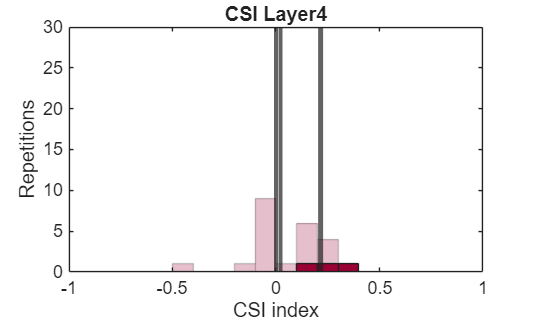

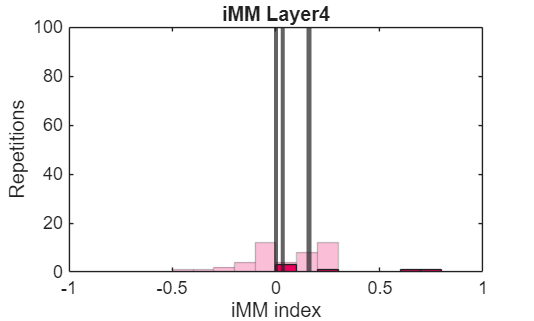

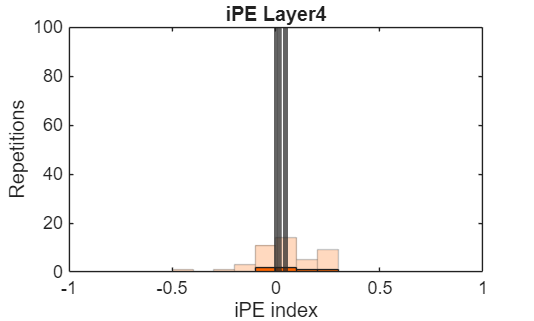

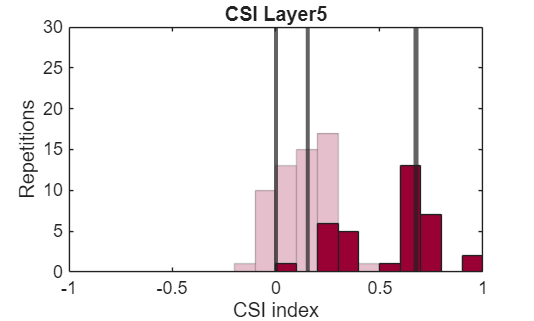

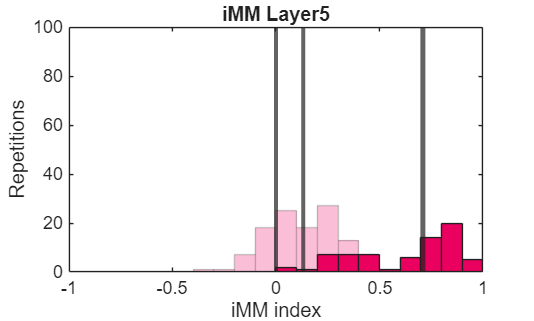

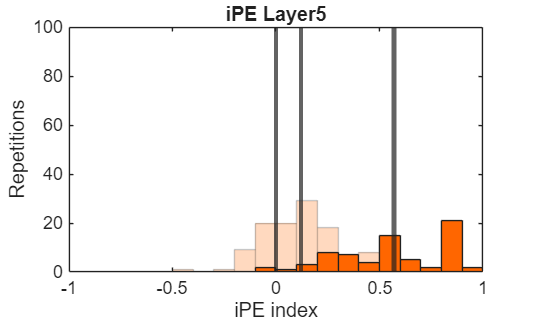

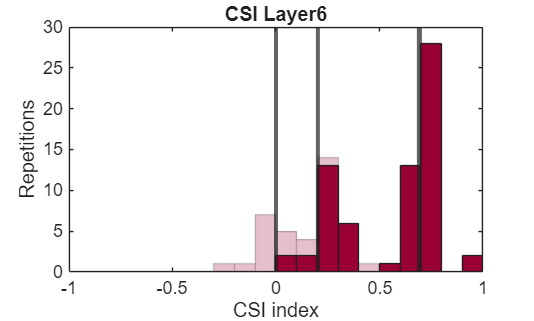

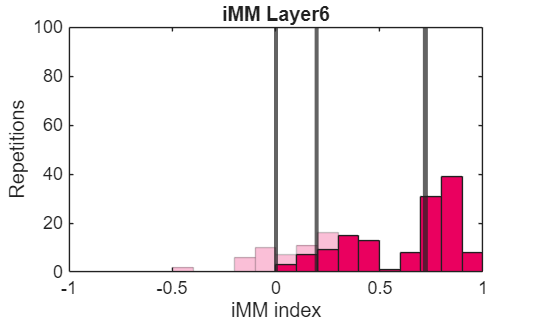

% Define layer names and corresponding tables
layers = {'Layer4', 'Layer5', 'Layer6'};
colors = {'#990033', '#EA005F', '#FF6600'}; % CSI, iMM, iPE colors
rangoY_CSI = [0 30]; % Example, replace with your actual range
rangoY = [0 100]; 

% Initialize p-values container
pValues = [];

for l = 1:length(layers)
    layer = layers{l};
    eval(sprintf('Table_Aud = %s_Aud;', layer));
    eval(sprintf('Table_Sig = %s_Sig;', layer));
    
    % CSI
    figure;
    histogram(Table_Aud.CSI, 'BinWidth',0.1, 'FaceColor',colors{1}, 'FaceAlpha',.25, 'EdgeAlpha',.25); hold on;
    histogram(Table_Sig.CSI, 'BinWidth',0.1, 'FaceColor',colors{1}, 'FaceAlpha',1, 'EdgeAlpha',1);
    xlim([-1 1]); ylim(rangoY_CSI); xline(0,'LineWidth',2);
    title(['CSI ' layer]); xlabel('CSI index'); ylabel('Repetitions');

    CSI_Median = median(Table_Aud.CSI, "omitnan");
    xline(CSI_Median, 'LineWidth', 2);
    CSI_Median_S = median(Table_Sig.CSI, "omitnan");
    xline(CSI_Median_S, 'LineWidth', 2.5);

    [~, p_CSI] = ttest(Table_Aud.CSI);
    [~, p_CSI_S] = ttest(Table_Sig.CSI);
    pValues = [pValues; p_CSI; p_CSI_S];

    cd 'D:\V1_Cortex_Paper\MultichannelDataTanks\Indexes';
    saveas(gcf, ['CSI_' layer '.pdf']);
    saveas(gcf, ['CSI_' layer '.tif']);
    saveas(gcf, ['CSI_' layer '.fig']);
    hold off;

    % iMM
    iMM_Aud = cat(1, Table_Aud.iMM1ca, Table_Aud.iMM2cd);
    iMM_Sig = cat(1, Table_Sig.iMM1ca, Table_Sig.iMM2cd);

    figure;
    histogram(iMM_Aud,'BinWidth',0.1,'FaceColor',colors{2},'FaceAlpha',.25,'EdgeAlpha',.25); hold on;
    histogram(iMM_Sig,'BinWidth',0.1,'FaceColor',colors{2},'FaceAlpha',1,'EdgeAlpha',1);
    xlim([-1 1]); ylim(rangoY); xline(0,'LineWidth',2);
    title(['iMM ' layer]); xlabel('iMM index'); ylabel('Repetitions');

    iMM_Median = nanmedian(iMM_Aud);
    xline(iMM_Median,'LineWidth',2);
    iMM_Median_S = nanmedian(iMM_Sig);
    xline(iMM_Median_S,'LineWidth',2.5);

    [~, p_iMM] = ttest(iMM_Aud);
    [~, p_iMM_S] = ttest(iMM_Sig);
    pValues = [pValues; p_iMM; p_iMM_S];

    cd 'D:\V1_Cortex_Paper\MultichannelDataTanks\Indexes';
    saveas(gcf, ['iMM_' layer '.pdf']);
    saveas(gcf, ['iMM_' layer '.tif']);
    saveas(gcf, ['iMM_' layer '.fig']);
    hold off;

    % iPE
    iPE_Aud = cat(1, Table_Aud.iPE1ca, Table_Aud.iPE2cd);
    iPE_Sig = cat(1, Table_Sig.iPE1ca, Table_Sig.iPE2cd);

    figure;
    histogram(iPE_Aud,'BinWidth',0.1,'FaceColor',colors{3},'FaceAlpha',.25,'EdgeAlpha',.25); hold on;
    histogram(iPE_Sig,'BinWidth',0.1,'FaceColor',colors{3},'FaceAlpha',1,'EdgeAlpha',1);
    xlim([-1 1]); ylim(rangoY); xline(0,'LineWidth',2);
    title(['iPE ' layer]); xlabel('iPE index'); ylabel('Repetitions');

    iPE_Median = nanmedian(iPE_Aud);
    xline(iPE_Median,'LineWidth',2);
    iPE_Median_S = nanmedian(iPE_Sig);
    xline(iPE_Median_S,'LineWidth',2.5);

    [~, p_iPE] = ttest(iPE_Aud);
    [~, p_iPE_S] = ttest(iPE_Sig);
    pValues = [pValues; p_iPE; p_iPE_S];

    cd 'D:\V1_Cortex_Paper\MultichannelDataTanks\Indexes';
    saveas(gcf, ['iPE_' layer '.pdf']);
    saveas(gcf, ['iPE_' layer '.tif']);
    saveas(gcf, ['iPE_' layer '.fig']);
    hold off;
end


% Bonferroni correction
m = length(pValues);
alpha = 0.05;
correctedP = pValues * m;
table(pValues, correctedP, 'VariableNames', {'pValue', 'BonferroniCorrected_pValue'})

ans = 18×2 table
      pValue      BonferroniCorrected_pValue
    __________    __________________________

       0.17685                3.1834        
      0.062777                  1.13        
      0.049798               0.89637        
      0.079377                1.4288        
      0.064083                1.1535        
       0.22026                3.9648        
    4.4856e-09             8.074e-08        
    6.8748e-16            1.2375e-14        
      3.02e-12            5.4359e-11        
    1.2158e-31            2.1884e-30        
    1.7463e-10            3.1433e-09        
     5.519e-28            9.9341e-27        
    6.0413e-06            0.00010874        
     1.715e-29             3.087e-28        
    7.0891e-09             1.276e-07        
    8.4956e-58            1.5292e-56        



Layer4:


Median Aud: 0.002 ± 0.020 | p(ttest)=0.444 | p(KS)=0.000 | p(AD)=0.013


Median Sig: 0.083 ± 0.108 | p(ttest)=0.089 | p(KS)=0.059 | p(AD)=0.029


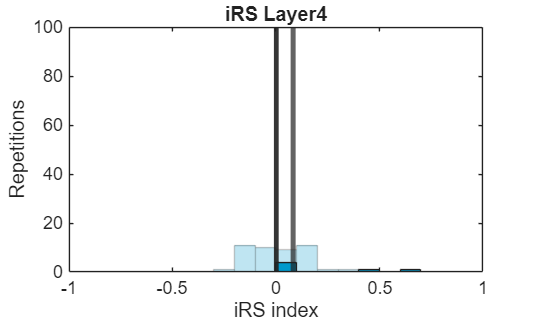


Layer5:


Median Aud: -0.004 ± 0.017 | p(ttest)=0.510 | p(KS)=0.000 | p(AD)=0.001


Median Sig: 0.034 ± 0.012 | p(ttest)=0.000 | p(KS)=0.000 | p(AD)=0.001


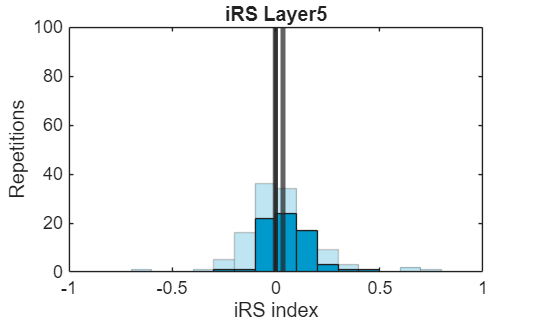


Layer6:


Median Aud: 0.016 ± 0.018 | p(ttest)=0.035 | p(KS)=0.000 | p(AD)=0.001


Median Sig: 0.045 ± 0.009 | p(ttest)=0.000 | p(KS)=0.000 | p(AD)=0.001


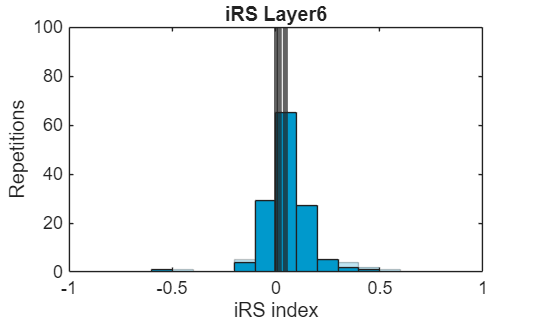

% Example code for iRS histograms Layer 4, 5, 6

layers = {'Layer4', 'Layer5', 'Layer6'};
save_path = 'D:\V1_Cortex_Paper\MultichannelDataTanks\Indexes'; 
rangoY = [0 100]; % Adjust Y-axis limits

for l = 1:length(layers)
    layer = layers{l};
    % Load tables
    eval(sprintf('Aud = %s_Aud;', layer));
    eval(sprintf('Sig = %s_Sig;', layer));
    
    % Concatenate iRS values
    iRScasc_Aud = cat(1, Aud.iRS1ca, Aud.iRS2cd);
    iRScasc_Sig = cat(1, Sig.iRS1ca, Sig.iRS2cd);
    
    figure;
    % Auditory histogram
    histogram(iRScasc_Aud,'BinWidth',0.1,'FaceColor','#0099CC','FaceAlpha',.25,'EdgeAlpha',.25);
    hold on
    % Significant histogram
    histogram(iRScasc_Sig,'BinWidth',0.1,'FaceColor','#0099CC','FaceAlpha',1,'EdgeAlpha',1);
    xlim([-1 1]); ylim(rangoY);
    xline(0,'LineWidth',2);
    title(['iRS ' layer]);
    xlabel('iRS index'); ylabel('Repetitions');
    
    % Median + SEM lines
    median_Aud = nanmedian(iRScasc_Aud);
    err_Aud = nanstd(iRScasc_Aud)/sqrt(numel(iRScasc_Aud));
    xline(median_Aud,'LineWidth',2.5);
    
    median_Sig = nanmedian(iRScasc_Sig);
    err_Sig = nanstd(iRScasc_Sig)/sqrt(numel(iRScasc_Sig));
    xline(median_Sig,'LineWidth',2.5);
    
    % Statistical tests
    [~, p_ttest_Aud] = ttest(iRScasc_Aud);
    [~, p_ttest_Sig] = ttest(iRScasc_Sig);
    [~, p_ks_Aud] = kstest(iRScasc_Aud);
    [~, p_ks_Sig] = kstest(iRScasc_Sig);
    [~, p_ad_Aud] = adtest(iRScasc_Aud);
    [~, p_ad_Sig] = adtest(iRScasc_Sig);
    
    % Display results
    fprintf('\n%s:\n', layer);
    fprintf('Median Aud: %.3f ± %.3f | p(ttest)=%.3f | p(KS)=%.3f | p(AD)=%.3f\n', ...
        median_Aud, err_Aud, p_ttest_Aud, p_ks_Aud, p_ad_Aud);
    fprintf('Median Sig: %.3f ± %.3f | p(ttest)=%.3f | p(KS)=%.3f | p(AD)=%.3f\n', ...
        median_Sig, err_Sig, p_ttest_Sig, p_ks_Sig, p_ad_Sig);
    
    % Save figures
    saveas(gcf, fullfile(save_path, ['iRS_' layer '.pdf']));
    saveas(gcf, fullfile(save_path, ['iRS_' layer '.tif']));
    saveas(gcf, fullfile(save_path, ['iRS_' layer '.fig']));
    hold off
end

% Define parameters
layers = {'Layer5', 'Layer6'};
colors = {'#990033', '#EA005F', '#FF6600'}; % CSI, iMM, iPE colors
index_names = {'iMM', 'iPE', 'iRS'};
% rangoY_CSI = [0 30];
rangoY = [0 100];
save_path = 'D:\V1_Cortex_Paper\MultichannelDataTanks\Indexes';

% Initialize result table
results = table;

% Begin layer-wise analysis
for l = 1:length(layers)
    layer = layers{l};
    eval(sprintf('Aud = %s_Aud;', layer));
    eval(sprintf('Sig = %s_Sig;', layer));

    % ---------- iMM ----------
    iMM_Aud = cat(1, Aud.iMM1ca, Aud.iMM2cd);
    iMM_Sig = cat(1, Sig.iMM1ca, Sig.iMM2cd);
    fig = figure;
    histogram(iMM_Aud, 'BinWidth',0.1, 'FaceColor',colors{2}, 'FaceAlpha',.25); hold on;
    histogram(iMM_Sig, 'BinWidth',0.1, 'FaceColor',colors{2}, 'FaceAlpha',1);
    xlim([-1 1]); ylim(rangoY); xline(0, 'LineWidth', 2);
    title(['iMM ' layer]); xlabel('iMM index'); ylabel('Repetitions');
    
    m_A = nanmedian(iMM_Aud); sem_A = nanstd(iMM_Aud)/sqrt(sum(~isnan(iMM_Aud)));
    m_S = nanmedian(iMM_Sig); sem_S = nanstd(iMM_Sig)/sqrt(sum(~isnan(iMM_Sig)));
    xline(m_A, 'LineWidth', 2); xline(m_S, 'LineWidth', 2.5);
    [~, p_A] = ttest(iMM_Aud); [~, p_S] = ttest(iMM_Sig);

    saveas(fig, fullfile(save_path, ['iMM_' layer '.pdf']));
    saveas(fig, fullfile(save_path, ['iMM_' layer '.tif']));
    close(fig)

    results = [results; 
        {layer, 'iMM', 'Auditory', m_A, sem_A, p_A, NaN}; 
        {layer, 'iMM', 'Significant', m_S, sem_S, p_S, NaN}];

    % ---------- iPE ----------
    iPE_Aud = cat(1, Aud.iPE1ca, Aud.iPE2cd);
    iPE_Sig = cat(1, Sig.iPE1ca, Sig.iPE2cd);
    fig = figure;
    histogram(iPE_Aud, 'BinWidth',0.1, 'FaceColor',colors{3}, 'FaceAlpha',.25); hold on;
    histogram(iPE_Sig, 'BinWidth',0.1, 'FaceColor',colors{3}, 'FaceAlpha',1);
    xlim([-1 1]); ylim(rangoY); xline(0, 'LineWidth', 2);
    title(['iPE ' layer]); xlabel('iPE index'); ylabel('Repetitions');
    
    m_A = nanmedian(iPE_Aud); sem_A = nanstd(iPE_Aud)/sqrt(sum(~isnan(iPE_Aud)));
    m_S = nanmedian(iPE_Sig); sem_S = nanstd(iPE_Sig)/sqrt(sum(~isnan(iPE_Sig)));
    xline(m_A, 'LineWidth', 2); xline(m_S, 'LineWidth', 2.5);
    [~, p_A] = ttest(iPE_Aud); [~, p_S] = ttest(iPE_Sig);

    saveas(fig, fullfile(save_path, ['iPE_' layer '.pdf']));
    saveas(fig, fullfile(save_path, ['iPE_' layer '.tif']));
    close(fig)

    results = [results; 
        {layer, 'iPE', 'Auditory', m_A, sem_A, p_A, NaN}; 
        {layer, 'iPE', 'Significant', m_S, sem_S, p_S, NaN}];

    % ---------- iRS ----------
    iRS_Aud = cat(1, Aud.iRS1ca, Aud.iRS2cd);
    iRS_Sig = cat(1, Sig.iRS1ca, Sig.iRS2cd);
    fig = figure;
    histogram(iRS_Aud, 'BinWidth',0.1, 'FaceColor','#0099CC', 'FaceAlpha',.25); hold on;
    histogram(iRS_Sig, 'BinWidth',0.1, 'FaceColor','#0099CC', 'FaceAlpha',1);
    xlim([-1 1]); ylim(rangoY); xline(0, 'LineWidth', 2);
    title(['iRS ' layer]); xlabel('iRS index'); ylabel('Repetitions');

    m_A = nanmedian(iRS_Aud); sem_A = nanstd(iRS_Aud)/sqrt(sum(~isnan(iRS_Aud)));
    m_S = nanmedian(iRS_Sig); sem_S = nanstd(iRS_Sig)/sqrt(sum(~isnan(iRS_Sig)));
    xline(m_A, 'LineWidth', 2.5); xline(m_S, 'LineWidth', 2.5);
    [~, p_A] = ttest(iRS_Aud); [~, p_S] = ttest(iRS_Sig);

    saveas(fig, fullfile(save_path, ['iRS_' layer '.pdf']));
    saveas(fig, fullfile(save_path, ['iRS_' layer '.tif']));
    close(fig)

    results = [results; 
        {layer, 'iRS', 'Auditory', m_A, sem_A, p_A, NaN}; 
        {layer, 'iRS', 'Significant', m_S, sem_S, p_S, NaN}];
end

% Add Bonferroni correction
results.Properties.VariableNames = {'Layer', 'Index', 'Group', 'Median', 'SEM', 'pValue', 'Bonferroni_p'};
non_nan_p = ~isnan(results.pValue);
results.Bonferroni_p(non_nan_p) = results.pValue(non_nan_p) * sum(non_nan_p);
results.Bonferroni_p(results.Bonferroni_p > 1) = 1;

% Save to Excel
excel_path = fullfile(save_path, 'Auditory_Significant_Index_Statistics.xlsx');
writetable(results, excel_path);

% Define parameters
layers = {'Layer5', 'Layer6'};
colors = {'#990033', '#EA005F', '#FF6600'}; % CSI, iMM, iPE colors
index_names = {'iMM', 'iPE', 'iRS'};
rangoY = [0 100];
save_path = 'D:\V1_Cortex_Paper\MultichannelDataTanks\Indexes';

% Initialize result table with Median & IQR fields
results = table('Size',[0 12], ...
    'VariableTypes', {'string','string','string','double','double','double','double','double','double','double','double','string'}, ...
    'VariableNames', {'Layer','Index','Group','N','Median','Q1','Q3','IQR','SEM','pValue','Bonferroni_p','Median_IQR_str'});

% Begin layer-wise analysis
for l = 1:length(layers)
    layer = layers{l};
    eval(sprintf('Aud = %s_Aud;', layer));
    eval(sprintf('Sig = %s_Sig;', layer));

    %% ---------- iMM ----------
    iMM_Aud = cat(1, Aud.iMM1ca, Aud.iMM2cd);
    iMM_Sig = cat(1, Sig.iMM1ca, Sig.iMM2cd);

    fig = figure;
    histogram(iMM_Aud, 'BinWidth',0.1, 'FaceColor',colors{2}, 'FaceAlpha',.25); hold on;
    histogram(iMM_Sig, 'BinWidth',0.1, 'FaceColor',colors{2}, 'FaceAlpha',1);
    xlim([-1 1]); ylim(rangoY); xline(0, 'LineWidth', 2);
    title(['iMM ' layer]); xlabel('iMM index'); ylabel('Repetitions');

    [m_A, sem_A, q1_A, q3_A, n_A, fmt_A] = med_iqr_summary(iMM_Aud);
    [m_S, sem_S, q1_S, q3_S, n_S, fmt_S] = med_iqr_summary(iMM_Sig);
    xline(m_A, 'LineWidth', 2); xline(m_S, 'LineWidth', 2.5);
    [~, p_A] = ttest(iMM_Aud); [~, p_S] = ttest(iMM_Sig);

    saveas(fig, fullfile(save_path, ['iMM_' layer '.pdf']));
    saveas(fig, fullfile(save_path, ['iMM_' layer '.tif']));
    close(fig)

    results = [results;
        {layer,'iMM','Auditory',   n_A, m_A, q1_A, q3_A, q3_A-q1_A, sem_A, p_A, NaN, fmt_A};
        {layer,'iMM','Significant',n_S, m_S, q1_S, q3_S, q3_S-q1_S, sem_S, p_S, NaN, fmt_S}];

    %% ---------- iPE ----------
    iPE_Aud = cat(1, Aud.iPE1ca, Aud.iPE2cd);
    iPE_Sig = cat(1, Sig.iPE1ca, Sig.iPE2cd);

    fig = figure;
    histogram(iPE_Aud, 'BinWidth',0.1, 'FaceColor',colors{3}, 'FaceAlpha',.25); hold on;
    histogram(iPE_Sig, 'BinWidth',0.1, 'FaceColor',colors{3}, 'FaceAlpha',1);
    xlim([-1 1]); ylim(rangoY); xline(0, 'LineWidth', 2);
    title(['iPE ' layer]); xlabel('iPE index'); ylabel('Repetitions');

    [m_A, sem_A, q1_A, q3_A, n_A, fmt_A] = med_iqr_summary(iPE_Aud);
    [m_S, sem_S, q1_S, q3_S, n_S, fmt_S] = med_iqr_summary(iPE_Sig);
    xline(m_A, 'LineWidth', 2); xline(m_S, 'LineWidth', 2.5);
    [~, p_A] = ttest(iPE_Aud); [~, p_S] = ttest(iPE_Sig);

    saveas(fig, fullfile(save_path, ['iPE_' layer '.pdf']));
    saveas(fig, fullfile(save_path, ['iPE_' layer '.tif']));
    close(fig)

    results = [results;
        {layer,'iPE','Auditory',   n_A, m_A, q1_A, q3_A, q3_A-q1_A, sem_A, p_A, NaN, fmt_A};
        {layer,'iPE','Significant',n_S, m_S, q1_S, q3_S, q3_S-q1_S, sem_S, p_S, NaN, fmt_S}];

    %% ---------- iRS ----------
    iRS_Aud = cat(1, Aud.iRS1ca, Aud.iRS2cd);
    iRS_Sig = cat(1, Sig.iRS1ca, Sig.iRS2cd);

    fig = figure;
    histogram(iRS_Aud, 'BinWidth',0.1, 'FaceColor','#0099CC', 'FaceAlpha',.25); hold on;
    histogram(iRS_Sig, 'BinWidth',0.1, 'FaceColor','#0099CC', 'FaceAlpha',1);
    xlim([-1 1]); ylim(rangoY); xline(0, 'LineWidth', 2);
    title(['iRS ' layer]); xlabel('iRS index'); ylabel('Repetitions');

    [m_A, sem_A, q1_A, q3_A, n_A, fmt_A] = med_iqr_summary(iRS_Aud);
    [m_S, sem_S, q1_S, q3_S, n_S, fmt_S] = med_iqr_summary(iRS_Sig);
    xline(m_A, 'LineWidth', 2.5); xline(m_S, 'LineWidth', 2.5);
    [~, p_A] = ttest(iRS_Aud); [~, p_S] = ttest(iRS_Sig);

    saveas(fig, fullfile(save_path, ['iRS_' layer '.pdf']));
    saveas(fig, fullfile(save_path, ['iRS_' layer '.tif']));
    close(fig)

    results = [results;
        {layer,'iRS','Auditory',   n_A, m_A, q1_A, q3_A, q3_A-q1_A, sem_A, p_A, NaN, fmt_A};
        {layer,'iRS','Significant',n_S, m_S, q1_S, q3_S, q3_S-q1_S, sem_S, p_S, NaN, fmt_S}];
end

% Bonferroni correction (same logic as your code)
non_nan_p = ~isnan(results.pValue);
results.Bonferroni_p(non_nan_p) = results.pValue(non_nan_p) * sum(non_nan_p);
results.Bonferroni_p(results.Bonferroni_p > 1) = 1;

% Save to Excel (same file)
excel_path = fullfile(save_path, 'Auditory_Significant_Index_Statistics.xlsx');
writetable(results, excel_path, 'WriteMode','overwritesheet');

%% -------- helper: median/IQR/SEM + formatted string --------
function [medv, semv, q1v, q3v, n, fmt] = med_iqr_summary(x)
    x = x(:);
    x = x(~isnan(x));
    n = numel(x);
    if n == 0
        medv = NaN; semv = NaN; q1v = NaN; q3v = NaN; fmt = "NaN [NaN–NaN]";
        return
    end
    medv = median(x);                         % robust center
    q = prctile(x,[25 75]);                   % Q1 & Q3
    q1v = q(1); q3v = q(2);
    semv = std(x) / sqrt(n);                  % keep your SEM for reference
    fmt = sprintf('%.3f [%.3f–%.3f]', medv, q1v, q3v);
end

%% ---- ADD-ON: Sign test (signtest vs 0) per Layer × Index × Group ----
% Append p-values to your existing 'results' table and save to same Excel
layers = {'Layer5','Layer6'};
indices = {'iMM','iPE','iRS'};
save_path = 'D:\V1_Cortex_Paper\MultichannelDataTanks\Indexes';
excel_path = fullfile(save_path, 'Auditory_Significant_Index_Statistics.xlsx');

pSign = table('Size',[0 4], ...
    'VariableTypes', {'string','string','string','double'}, ...
    'VariableNames', {'Layer','Index','Group','pSignTest'});

for l = 1:numel(layers)
    layer = layers{l};
    eval(sprintf('Aud = %s_Aud;', layer));
    eval(sprintf('Sig = %s_Sig;', layer));

    % helper to extract the correct vectors
    getv = @(T, name) switch_idx(T, name);

    for ii = 1:numel(indices)
        idx = indices{ii};

        % Auditory
        xA = getv(Aud, idx); xA = xA(~isnan(xA));
        pA = NaN; if ~isempty(xA), pA = signtest(xA, 0); end
        pSign = [pSign; {layer, idx, 'Auditory', pA}];

        % Significant
        xS = getv(Sig, idx); xS = xS(~isnan(xS));
        pS = NaN; if ~isempty(xS), pS = signtest(xS, 0); end
        pSign = [pSign; {layer, idx, 'Significant', pS}];
    end
end

% Add columns if not already present
if ~ismember('pSignTest', results.Properties.VariableNames)
    results.pSignTest = NaN(height(results),1);
end
if ~ismember('Bonferroni_pSignTest', results.Properties.VariableNames)
    results.Bonferroni_pSignTest = NaN(height(results),1);
end

% Merge results by (Layer, Index, Group)
for k = 1:height(pSign)
    mask = strcmp(results.Layer, pSign.Layer(k)) & ...
           strcmp(results.Index, pSign.Index(k)) & ...
           strcmp(results.Group, pSign.Group(k));
    results.pSignTest(mask) = pSign.pSignTest(k);
end

% Apply Bonferroni correction to signtest p-values
nn = ~isnan(results.pSignTest);
m = sum(nn);
results.Bonferroni_pSignTest(nn) = min(1, results.pSignTest(nn) * m);

% Save to same Excel file (overwrite sheet)
writetable(results, excel_path, 'WriteMode','overwritesheet');

%% ---- helper to build vectors per index ----
function v = switch_idx(T, idxname)
    switch idxname
        case 'iMM'
            v = cat(1, T.iMM1ca, T.iMM2cd);
        case 'iPE'
            v = cat(1, T.iPE1ca, T.iPE2cd);
        case 'iRS'
            v = cat(1, T.iRS1ca, T.iRS2cd);
        otherwise
            error('Unknown index %s', idxname);
    end
end


% Define parameters
layers = {'Layer5', 'Layer6'};
colors = {'#990033', '#EA005F', '#FF6600'}; % CSI, iMM, iPE colors
index_names = {'iMM', 'iPE', 'iRS'};
rangoY = [0 100];
save_path = 'D:\V1_Cortex_Paper\MultichannelDataTanks\Indexes';

% Initialize result table
results = table;

% Begin layer-wise analysis
for l = 1:length(layers)
    layer = layers{l};
    eval(sprintf('Aud = %s_Aud;', layer));
    eval(sprintf('Sig = %s_Sig;', layer));

    % ---------- iMM ----------
    iMM_Aud = cat(1, Aud.iMM1ca, Aud.iMM2cd);
    iMM_Sig = cat(1, Sig.iMM1ca, Sig.iMM2cd);
    fig = figure;
    histogram(iMM_Aud, 'BinWidth',0.1, 'FaceColor',colors{2}, 'FaceAlpha',.25); hold on;
    histogram(iMM_Sig, 'BinWidth',0.1, 'FaceColor',colors{2}, 'FaceAlpha',1);
    xlim([-1 1]); ylim(rangoY); xline(0, 'LineWidth', 2);
    title(['iMM ' layer]); xlabel('iMM index'); ylabel('Repetitions');
    
    m_A = nanmedian(iMM_Aud); sem_A = nanstd(iMM_Aud)/sqrt(sum(~isnan(iMM_Aud)));
    m_S = nanmedian(iMM_Sig); sem_S = nanstd(iMM_Sig)/sqrt(sum(~isnan(iMM_Sig)));
    xline(m_A, 'LineWidth', 2); xline(m_S, 'LineWidth', 2.5);
    [~, p_A] = ttest(iMM_Aud); [~, p_S] = ttest(iMM_Sig);
    [BC_A, mode_A] = bimodality_test(iMM_Aud);
    [BC_S, mode_S] = bimodality_test(iMM_Sig);

    saveas(fig, fullfile(save_path, ['iMM_' layer '.pdf']));
    saveas(fig, fullfile(save_path, ['iMM_' layer '.tif']));
    close(fig)

    results = [results; 
        {layer, 'iMM', 'Auditory', m_A, sem_A, p_A, NaN, BC_A, mode_A}; 
        {layer, 'iMM', 'Significant', m_S, sem_S, p_S, NaN, BC_S, mode_S}];

    % ---------- iPE ----------
    iPE_Aud = cat(1, Aud.iPE1ca, Aud.iPE2cd);
    iPE_Sig = cat(1, Sig.iPE1ca, Sig.iPE2cd);
    fig = figure;
    histogram(iPE_Aud, 'BinWidth',0.1, 'FaceColor',colors{3}, 'FaceAlpha',.25); hold on;
    histogram(iPE_Sig, 'BinWidth',0.1, 'FaceColor',colors{3}, 'FaceAlpha',1);
    xlim([-1 1]); ylim(rangoY); xline(0, 'LineWidth', 2);
    title(['iPE ' layer]); xlabel('iPE index'); ylabel('Repetitions');
    
    m_A = nanmedian(iPE_Aud); sem_A = nanstd(iPE_Aud)/sqrt(sum(~isnan(iPE_Aud)));
    m_S = nanmedian(iPE_Sig); sem_S = nanstd(iPE_Sig)/sqrt(sum(~isnan(iPE_Sig)));
    xline(m_A, 'LineWidth', 2); xline(m_S, 'LineWidth', 2.5);
    [~, p_A] = ttest(iPE_Aud); [~, p_S] = ttest(iPE_Sig);
    [BC_A, mode_A] = bimodality_test(iPE_Aud);
    [BC_S, mode_S] = bimodality_test(iPE_Sig);

    saveas(fig, fullfile(save_path, ['iPE_' layer '.pdf']));
    saveas(fig, fullfile(save_path, ['iPE_' layer '.tif']));
    close(fig)

    results = [results; 
        {layer, 'iPE', 'Auditory', m_A, sem_A, p_A, NaN, BC_A, mode_A}; 
        {layer, 'iPE', 'Significant', m_S, sem_S, p_S, NaN, BC_S, mode_S}];

    % ---------- iRS ----------
    iRS_Aud = cat(1, Aud.iRS1ca, Aud.iRS2cd);
    iRS_Sig = cat(1, Sig.iRS1ca, Sig.iRS2cd);
    fig = figure;
    histogram(iRS_Aud, 'BinWidth',0.1, 'FaceColor','#0099CC', 'FaceAlpha',.25); hold on;
    histogram(iRS_Sig, 'BinWidth',0.1, 'FaceColor','#0099CC', 'FaceAlpha',1);
    xlim([-1 1]); ylim(rangoY); xline(0, 'LineWidth', 2);
    title(['iRS ' layer]); xlabel('iRS index'); ylabel('Repetitions');

    m_A = nanmedian(iRS_Aud); sem_A = nanstd(iRS_Aud)/sqrt(sum(~isnan(iRS_Aud)));
    m_S = nanmedian(iRS_Sig); sem_S = nanstd(iRS_Sig)/sqrt(sum(~isnan(iRS_Sig)));
    xline(m_A, 'LineWidth', 2.5); xline(m_S, 'LineWidth', 2.5);
    [~, p_A] = ttest(iRS_Aud); [~, p_S] = ttest(iRS_Sig);
    [BC_A, mode_A] = bimodality_test(iRS_Aud);
    [BC_S, mode_S] = bimodality_test(iRS_Sig);

    saveas(fig, fullfile(save_path, ['iRS_' layer '.pdf']));
    saveas(fig, fullfile(save_path, ['iRS_' layer '.tif']));
    close(fig)

    results = [results; 
        {layer, 'iRS', 'Auditory', m_A, sem_A, p_A, NaN, BC_A, mode_A}; 
        {layer, 'iRS', 'Significant', m_S, sem_S, p_S, NaN, BC_S, mode_S}];
end

% Add Bonferroni correction
results.Properties.VariableNames = {'Layer', 'Index', 'Group', 'Median', 'SEM', 'pValue', 'Bonferroni_p', 'BimodalityCoefficient', 'Modality'};
non_nan_p = ~isnan(results.pValue);
results.Bonferroni_p(non_nan_p) = results.pValue(non_nan_p) * sum(non_nan_p);
results.Bonferroni_p(results.Bonferroni_p > 1) = 1;

% Save to Excel
excel_path = fullfile(save_path, 'Auditory_Significant_Index_Statistics_With_Modality.xlsx');
writetable(results, excel_path);


%% Bimodality Coefficient Test Function
function [BC, modality] = bimodality_test(data)
    data = data(~isnan(data));
    g = skewness(data);
    k = kurtosis(data); % MATLAB default is excess kurtosis
    n = length(data);
    BC = (g^2 + 1) / (k + (3*(n-1)^2)/((n-2)*(n-3))); % adjusted formula for finite samples
    if BC > 0.555
        modality = 'bimodal';
    else
        modality = 'unimodal';
    end
end